% Clear Workspace
clear all
clc

% Read STL File
stl1 = stlread("Test Objects\Box.STL");

% Create UniformSliceGeneratorObject
uSGO1 = FlatUniformSliceGenerator(stl1, 20)

uSGO1 =   FlatUniformSliceGenerator with properties:

                 obj: []
    connectivityList: [12×3 double]
       numOfElements: 12
              points: [8×3 int64]
      sliceThickness: 20
           slicePath: [0×3 double]


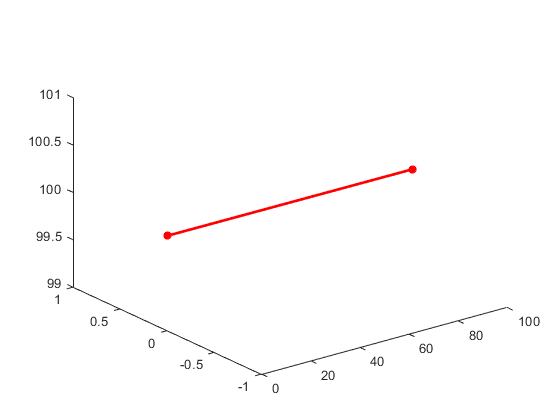

ans =      0   100     0
     0   100     0
     0   100     0
     0   100     0
     0     0     0
   100   100     0
   100     0     0
   100     0     0
   100     0     0
   100     0     0


ans =   FlatUniformSliceGenerator with properties:

                 obj: []
    connectivityList: [12×3 double]
       numOfElements: 12
              points: [8×3 int64]
      sliceThickness: 20
           slicePath: [116×3 double]



% Generate
figure(3)
uSGO1.generateSlices()

op = uSGO1.getSlicePath()

op =      0   100     0
     0   100     0
     0   100     0
     0   100     0
     0     0     0
   100   100     0
   100     0     0
   100     0     0
   100     0     0
   100     0     0


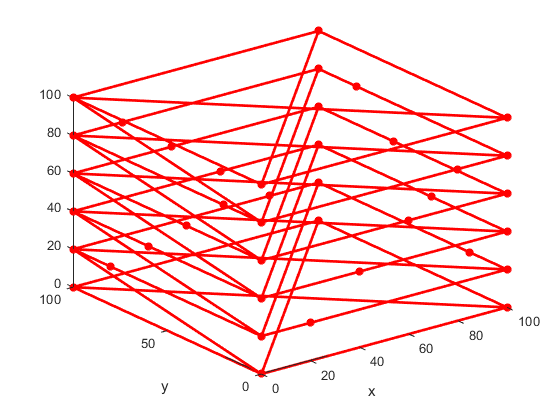


% Show
figure(4)
plot3(op(:,1), op(:,2), op(:,3),'-r*','LineWidth',2);
xlabel('x')
ylabel('y')
view(3);
hold on

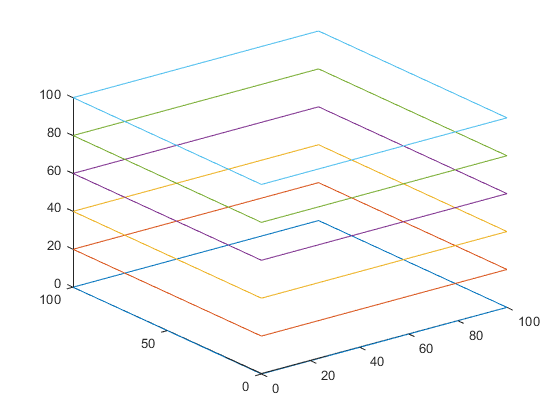


%edge detection test
%find unique
[C,ia,~] = unique(op(:,3));
for i=1:height(ia)-1
    x=op(ia(i):ia(i+1)-1,1);
    y=op(ia(i):ia(i+1)-1,2);
    k=boundary(x,y);
    z = zeros(height(x(k)),1);
    z(:)=C(i);
    figure(5);
    hold on
    plot3(x(k),y(k),z)
    slicePath = [x(k),y(k),z];
    
    %do last part
    if i==height(ia)-1
        x=op(ia(end):height(op),1);
        y=op(ia(end):height(op),2);
        k=boundary(x,y);
        z = zeros(height(x(k)),1);
        z(:)=C(end);
        figure(5);
        hold on
        plot3(x(k),y(k),z)
        slicePath = [x(k),y(k),z];
        
        view(3);
    end
end